# 图解机器学习代码系列：有监督回归

- [Zhihu: https://www.zhihu.com/people/1105936347](https://www.zhihu.com/people/1105936347)

- [Github: https://github.com/AFei19911012](https://github.com/AFei19911012)

## 最小二乘学习法

对模型输出和训练输出的平方误差达到最小时的参数 θ 进行学习


$$J_{LS}(\theta)=\frac{1}{2}||\Phi\theta-y||^2$$


求解简单，对 θ 求偏导数并令其为零，Matlab 使用左除即可

以三角多项式基函数为例


$$\phi(x)=(1, sin\frac{x}{2}, cos\frac{x}{2}, sin\frac{2x}{2}, cos\frac{2x}{2},..., sin\frac{15x}{2}, cos\frac{15x}{2})^T$$


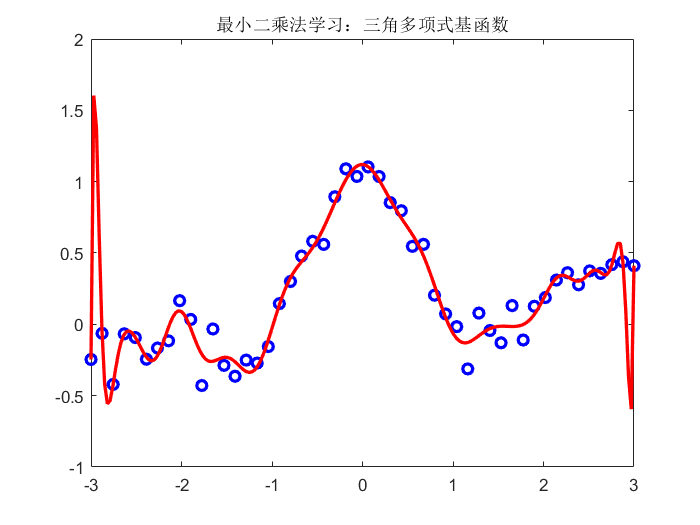

clear; clc;close all;
rng('default');
n = 50;
N = 200;
x = linspace(-3, 3, n)';
X = linspace(-3, 3, N)';
% 生成带有噪声的训练数据
y = sin(pi*x) ./ (pi*x) + 0.1*x + 0.1*randn(n, 1);
p(:, 1) = ones(n, 1);
P(:, 1) = ones(N, 1);
% 使用三角多项式基函数
for j = 1:15
    p(:, 2*j) = sin(j/2*x);
    p(:, 2*j+1) = cos(j/2*x);
    P(:, 2*j) = sin(j/2*X);
    P(:, 2*j+1) = cos(j/2*X);
end
% 计算训练的系数
t = p\y;
% 根据系数计算结果
F = P*t;
figure;
plot(x, y, 'bo', 'linewidth', 2);
hold on;
plot(X, F, 'r-', 'linewidth', 2);
hold off
title('最小二乘法学习：三角多项式基函数');

## 大规模数据学习：随机梯度法

- （1）θ 赋初始值；

- （2）对选定训练样本，采用梯度下降方式，更新 $\theta=\theta-\epsilon\phi(x_i)(f_{\theta}(x_i)-y_i)$

- （3）重复步骤（2）直到达到收敛精度

梯度法收敛速度强烈依赖梯度下降步幅及收敛结果的判断方法

### 高斯核函数模型

        
$$f_{\theta}(x)=\sum_{n=1}^N\theta_jK(x, x_j)\\
K(x,c)=exp(-\frac{||x-c||^2}{2h^2})$$


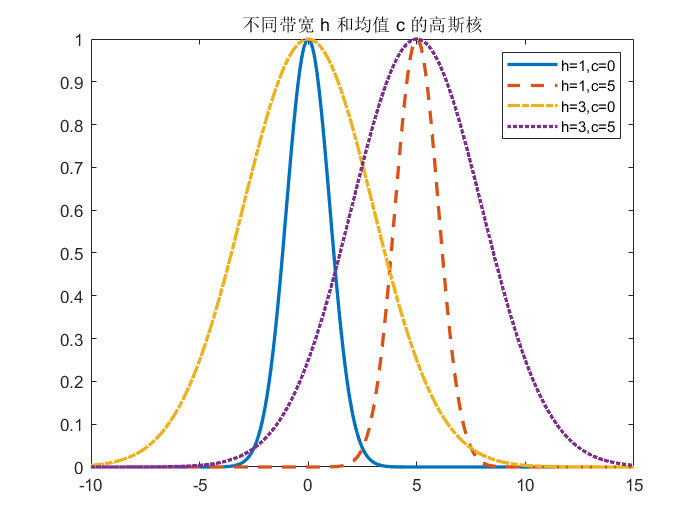

clear;clc;
rng('default');
x = -10:0.1:15;
h = [1, 1, 3, 3];
c = [0, 5, 0, 5];
linestyle = {'-', '--', '-.', ':'};
Guass = @(x, h, c) exp(-(x-c).^2/(2*h^2));
figure;
for i = 1:length(h)
    plot(x, Guass(x, h(i), c(i)), 'LineStyle', linestyle{i}, 'LineWidth', 2);
    hold on
end
hold off
legend('h=1,c=0', 'h=1,c=5', 'h=3,c=0', 'h=3,c=5');
title('不同带宽 h 和均值 c 的高斯核');

### 随机梯度法

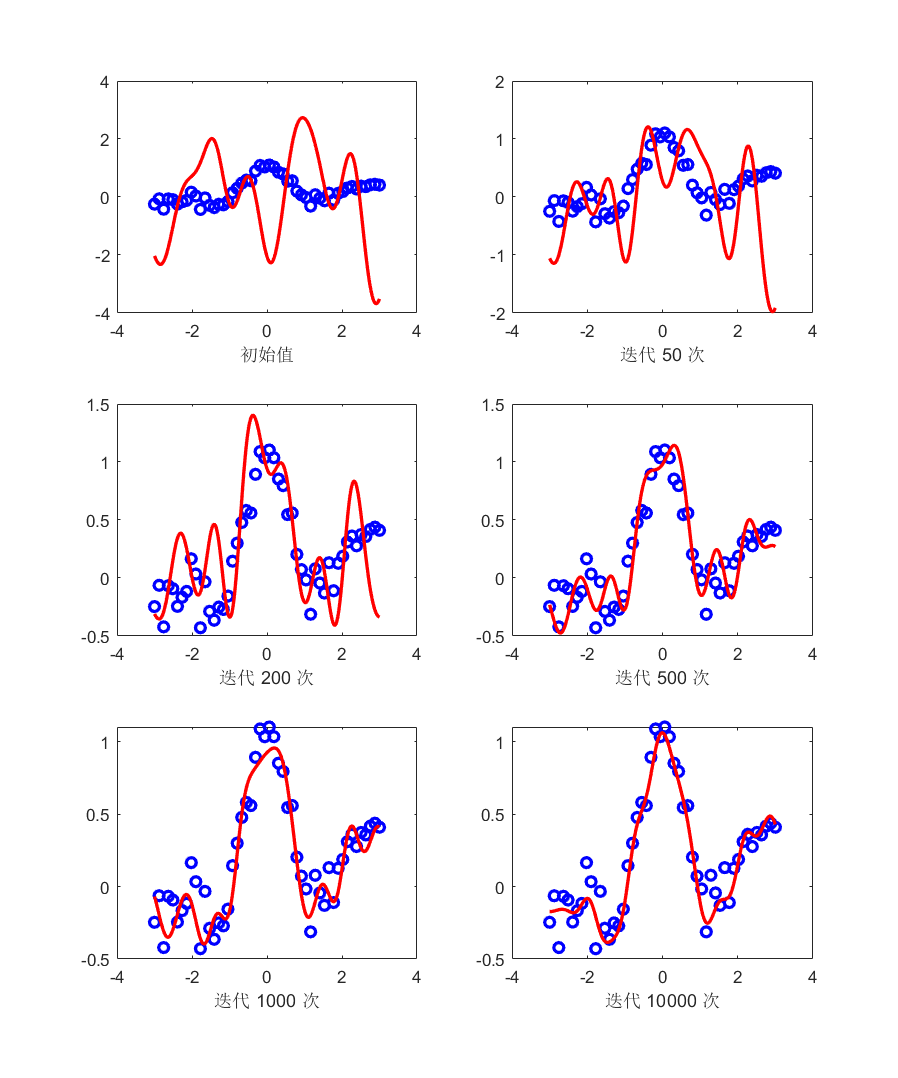

clear; clc;
rng('default');
n = 50;
N = 200;
x = linspace(-3, 3, n)';
X = linspace(-3, 3, N)';
% 生成带有噪声的训练数据
y = sin(pi*x) ./ (pi*x) + 0.1*x + 0.1*randn(n, 1);
hh = 2*0.3^2;
% 随机初始值
t0 = randn(n, 1);
% 梯度下降的步幅
e = 0.1;
% 核函数
K = exp(-(repmat(X.^2, 1, n) + repmat(x.^2', N, 1) - 2*X*x')/hh);
figure('Position', [10, 10, 1000, 1200]);
ites = [1, 50, 200, 500, 1000, 10000];
for ite = 1 : n*1000
    % 随机挑选
    i = randi(n, 1);
    ki = exp(-(x - x(i)).^2/hh);
    t = t0 - e*ki*(ki'*t0 - y(i));   % 梯度法
    % 达到收敛精度退出
    if norm(t - t0) < 1e-7
        break;
    end
    t0 = t;
    % 绘图
    for flag = 1:length(ites)
        if ite == ites(flag)
            F = K*t;
            subplot(3, 2, flag);
            plot(x, y, 'bo', 'linewidth', 2);
            hold on;
            plot(X, F, 'r', 'linewidth', 2);
            hold off
            if flag == 1
                xlabel('初始值');
            else
                xlabel(sprintf('迭代 %d 次', ite));
            end
            break;
        end
    end
end

## 部分空间约束的最小二乘学习法

把参数空间限制在一定范围内，防止过拟合现象

clear; clc;
rng('default');
n = 50;
N = 200;
x = linspace(-3, 3, n)';
X = linspace(-3, 3, N)';
% 生成带有噪声的训练数据
y = sin(pi*x) ./ (pi*x) + 0.1*x + 0.1*randn(n, 1);
p(:, 1) = ones(n, 1);
P(:, 1) = ones(N, 1);
% 使用三角多项式基函数
for j = 1:15
    p(:, 2*j) = sin(j/2*x);
    p(:, 2*j+1) = cos(j/2*x);
    P(:, 2*j) = sin(j/2*X);
    P(:, 2*j+1) = cos(j/2*X);
end
% 一般最小二乘
t1 = p\y;
F1 = P*t1;
% 部分空间约束
t2 = (p*diag([ones(1, 11), zeros(1, 20)]))\y;

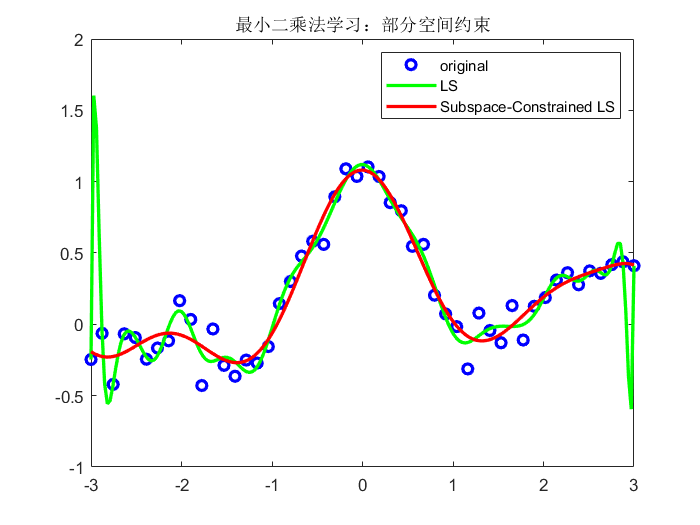

F2 = P*t2;
figure;
plot(x, y, 'bo', 'linewidth', 2);
hold on
plot(X, F1, 'g-', 'linewidth', 2);
plot(X, F2, 'r-', 'linewidth', 2);
hold off
legend('original', 'LS', 'Subspace-Constrained LS');
title('最小二乘法学习：部分空间约束');

## L2 约束的最小二乘学习法


$$J_{LS}(\theta)=\frac{1}{2}||\Phi\theta-y||^2 ,\quad ||\theta||^2\leq R$$
 

利用拉格朗日对偶问题可求解

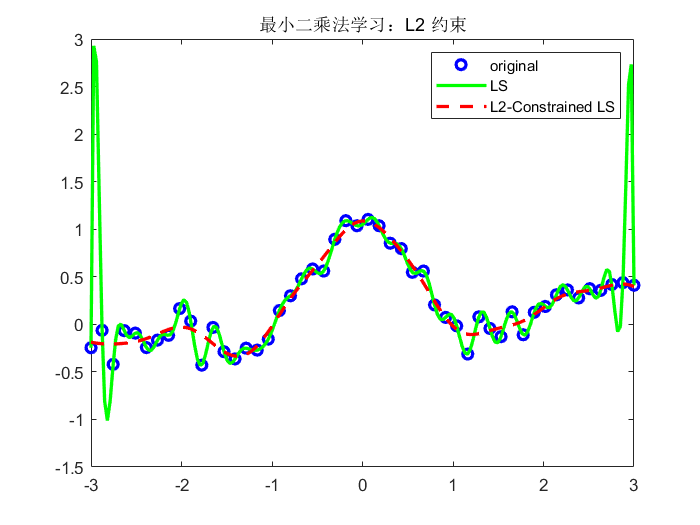

clear; clc;
rng('default');
n = 50;
N = 200;
x = linspace(-3, 3, n)';
X = linspace(-3, 3, N)';
% 生成带有噪声的训练数据
y = sin(pi*x) ./ (pi*x) + 0.1*x + 0.1*randn(n, 1);
x2 = x.^2;
X2 = X.^2;
hh = 2*0.3^2;
lambda = 0.1;
% 核函数
k = exp(-(repmat(x2, 1, n) + repmat(x2', n, 1) - 2*(x*x'))/hh);
K = exp(-(repmat(X2, 1, n) + repmat(x2', N, 1) - 2*X*x')/hh);
t1 = k\y;
F1 = K*t1;
% L2范数约束
t2 = (k^2 + lambda*eye(n))\(k*y);
F2 = K*t2;
figure;
plot(x, y, 'bo', 'linewidth', 2);
hold on;
plot(X, F1, 'g-', 'linewidth', 2);
plot(X, F2, 'r--', 'linewidth', 2);
hold off
legend('original', 'LS','L2-Constrained LS');
title('最小二乘法学习：L2 约束');

## 模型选择：泛化误差、交叉校验

对于训练样本的误差，选择泛化误差而不是训练平方误差达到最小对应的模型

### 部分空间约束、L2 约束

过分依赖正交投影矩阵和正则化参数

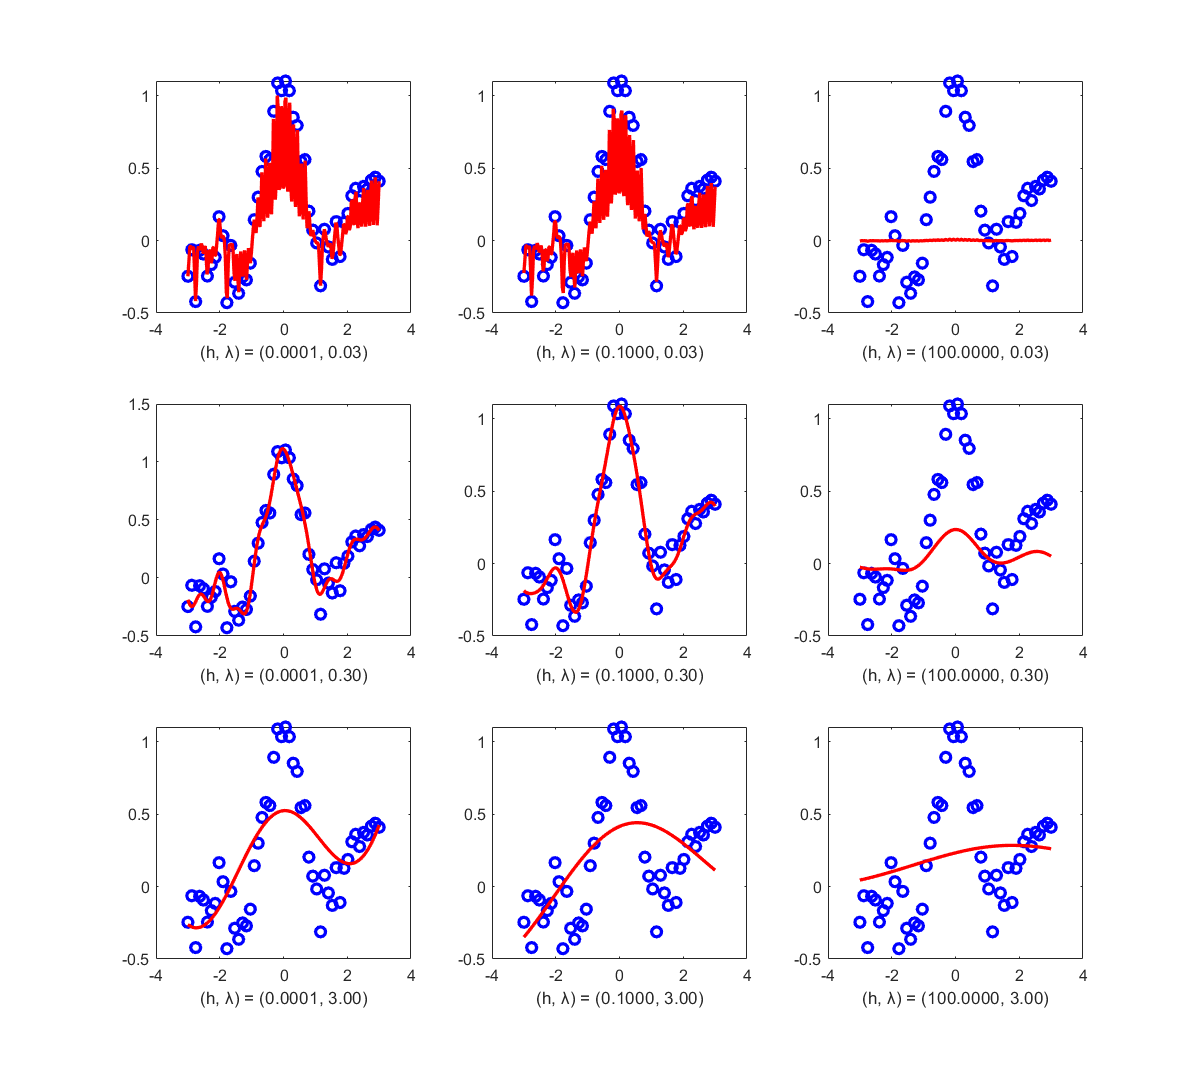

clear; clc;
rng('default');
n = 50;
N = 200;
x = linspace(-3, 3, n)';
X = linspace(-3, 3, N)';
% 生成带有噪声的训练数据
y = sin(pi*x) ./ (pi*x) + 0.1*x + 0.1*randn(n, 1);
x2 = x.^2;
X2 = X.^2;
% 带宽供选择
hhs = [0.03, 0.3, 3];
% 正则化参数供选择
ls = [0.0001, 0.1, 100];
figure('Position', [10, 10, 1000, 900]);
for i= 1:3
    for j = 1:3
        hh = 2*hhs(i)^2;
        lambda = ls(j);
        % 核函数
        k = exp(-(repmat(x2, 1, n) + repmat(x2', n, 1) - 2*(x*x'))/hh);
        K = exp(-(repmat(X2, 1, n) + repmat(x2', N, 1) - 2*X*x')/hh);
        % L2范数约束
        t = (k^2 + lambda*eye(n))\(k*y);
        F = K*t;
        subplot(3, 3, 3*(i-1)+j);
        plot(x, y, 'bo', 'linewidth', 2);
        hold on;
        plot(X, F, 'r-', 'linewidth', 2);
        hold off
        xlabel(sprintf('(h, λ) = (%.4f, %.2f)', lambda, hhs(i)));
    end
end

### 高斯核模型 L2 约束最小二乘学习法的交叉校验

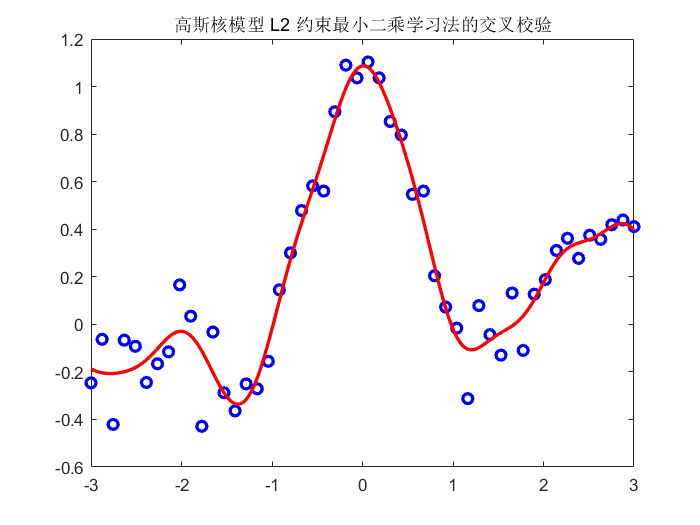

clear; clc;
rng('default');
n = 50;
N = 200;
x = linspace(-3, 3, n)';
X = linspace(-3, 3, N)';
pix = pi*x;
% 生成带有噪声的训练数据
y = sin(pi*x) ./ (pi*x) + 0.1*x + 0.1*randn(n, 1);
x2 =x.^2;
% || x - x(j) ||^2
xx = repmat(x2, 1, n) + repmat(x2', n, 1) - 2*(x*x');
% 带宽供选择
hhs = 2*[0.03, 0.3, 3] .^ 2;
% 正则化参数供选择
ls = [0.0001, 0.1, 100];
m = 5;
% 1~m 分别有 10 个
u = floor(m*(0 : n-1) / n) + 1;
u = u(randperm(n));
g = zeros(length(hhs), length(ls), m);
% 遍历带宽参数
for hk = 1 : length(hhs)
    % 带宽
    hh = hhs(hk);
    % 核函数
    k = exp(-xx / hh);
    % 训练样本分割为 m 个集合
    for i = 1 : m
        % 选择 40 个训练样本对应的核函数
        ki = k(u ~= i, :);
        % 剩下 10 个用于测试对应的核函数
        kc = k(u == i, :);
        % 选择 40 个训练样本
        yi = y( u ~= i);
        % 剩下 10 个样本用于测试
        yc = y( u == i );
        % 遍历正则化参数
        for lk = 1 : length(ls)
            % 正则化参数
            lam = ls(lk);
            % 训练参数
            t = (ki'*ki + lam*eye(n)) \ (ki'*yi);
            % 测试样本通过训练参数得到的结果
            fc = kc*t;
            % 泛化误差的评估值
            g(hk, lk, i) = mean((fc - yc) .^ 2);
        end
    end
end
% 五次验证泛化误差平均值
gh = mean(g, 3);
% 泛化误差最小值对应的下标
[h_index, l_index] = find(gh == min(min(gh)));
% 最佳正则化参数
L = ls(l_index);
% 最佳带宽
HH = hhs(h_index);
% 最佳核函数
K = exp(-(repmat(X .^ 2, 1, n) + repmat(x2', N, 1) - 2*X*x') / HH);
k = exp(-xx / HH);
t = (k^2 + L*eye(n)) \ (k*y);
F = K*t;
figure;
plot(x, y, 'ob', 'LineWidth', 2);
hold on;
plot(X, F, 'r', 'LineWidth', 2);
hold off
title('高斯核模型 L2 约束最小二乘学习法的交叉校验');

### 稀疏学习：L1 约束的最小二乘学习法（Lasso 回归）


$$J_{LS}(\theta)=\frac{1}{2}||\Phi\theta-y||^2, \quad ||\theta||_1\leq R$$


使用一般 L2 约束的最小二乘学习法求解

- （1）θ 赋初始值；

- （2）计算矩阵 $\Theta=diag(|\theta_1|, |\theta_2|, ..., |\theta_b|)$

- （3）计算解 $\theta = (\Phi^T\Phi+\lambda\Theta^+)^{-1}\Phi^Ty$

- （4）重复步骤（2）和（3）直到达到收敛精度

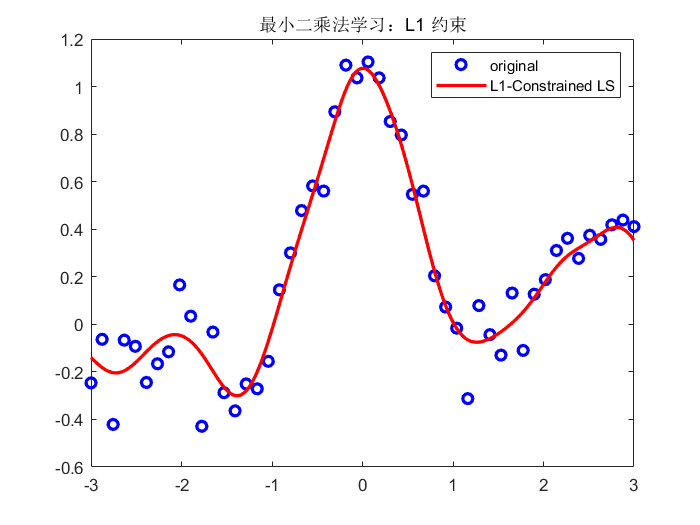

clear; clc;
rng('default');
n = 50;
N = 200;
x = linspace(-3, 3, n)';
X = linspace(-3, 3, N)';
% 生成带有噪声的训练数据
y = sin(pi*x) ./ (pi*x) + 0.1*x + 0.1*randn(n, 1);
x2 = x.^2;
X2 = X.^2;
hh = 2*0.3^2;
lambda = 0.1;
% 核函数
k = exp(-(repmat(x2, 1, n) + repmat(x2', n, 1) - 2*(x*x'))/hh);
k2 = k^2;
ky = k*y;
% 初始解
t0 = randn(n, 1);
for ite =1 : 1000
    t = (k2 + lambda*pinv(diag(abs(t0)))) \ ky;
    if norm(t- t0) < 1e-3
        break;
    end
    t0 = t;
end
K = exp(-(repmat(X.^2, 1, n) + repmat(x2', N, 1) - 2*X*x') / hh);
F = K*t;
figure;
plot(x, y, 'bo', 'linewidth', 2);
hold on;
plot(X, F, 'r-', 'linewidth', 2);
hold off
legend('original', 'L1-Constrained LS');
title('最小二乘法学习：L1 约束');

## 鲁棒学习

对异常值也能保持稳定、可靠的性质，称为鲁棒性

### Huber 损失最小化学习


$$\rho Huber(r)=
\left\{
\begin{array}{r}
r^2/2                      ,\quad (|r_i|\leq\eta)\\
\eta|r|-\eta^2/2      ,\quad (|r_i|>\eta)
\end{array} 
\right. $$


使用加权最小二乘学习法求解

- （1）θ 赋初始值；

- （2）计算权重矩阵 $W=diag(w_1,w_2,...,w_n), \quad 
w_i=
\left\{
\begin{array}{r}
1   ,\quad (|r_i|\leq\eta)\\
\eta/|r_i|, \quad (|r_i|>\eta)
\end{array} 
\right. ,\quad
r_i=f_\theta(x_i)-y_i$

- （3）计算解 $\theta = (\Phi^TW\Phi)^{-1}\Phi^TWy$

- （4）重复步骤（2）和（3）直到达到收敛精度

### Tukey 损失最小化学习

Tukey 损失最小化学习的结果依赖于初始值的选择，初始值一旦发生变化，或者数据量减少的话，就可能会得到完全不同的学习结果

使用加权最小二乘学习法求解

- （1）θ 赋初始值；

- （2）计算权重矩阵 $W=diag(w_1,w_2,...,w_n), \quad 
w_i=
\left\{
\begin{array}{r}
(1-r^2/\eta^2)^2   ,\quad (|r_i|\leq\eta)\\
0, \quad (|r_i|>\eta)
\end{array} 
\right. ,\quad
r_i=f_\theta(x_i)-y_i$

- （3）计算解 $\theta = (\Phi^TW\Phi)^{-1}\Phi^TWy$

- （4）重复步骤（2）和（3）直到达到收敛精度

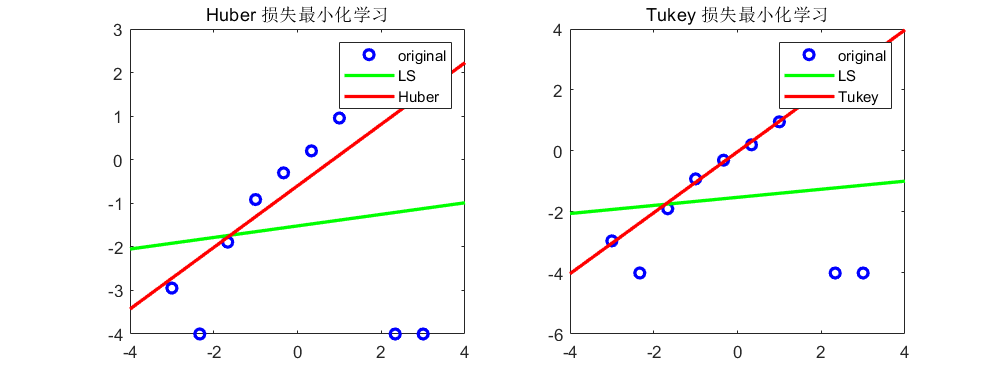

clear; clc;
rng('default');
n = 10;
N = 100;
x = linspace(-3, 3, n)';
X = linspace(-4, 4, N)';
% 生成带有噪声的训练数据
y = x + 0.1*randn(n, 1);
% 异常值
y([2, 9, 10]) = -4;
p(:, 1) = ones(n, 1);
p(:, 2) = x;
P(:, 1) = ones(N, 1);
P(:, 2) = X;
% 计算拟合系数，多项式拟合可以这么做
t0 = p\y;
% 一般拟合值
fit = P*t0;
% 阈值设定
e = 1;
methods = {'Huber', 'Tukey'};
figure('Position', [10, 10, 800, 300]);
for flag = 1:2
    for ite = 1 : 1000
        % 残差
        r = abs(p*t0 - y);
        if flag == 1
            % Huber 损失最小化学习
            w = ones(n, 1);
            w(r > e) = e ./ r(r > e);
        else
            % Tukey 损失最小化学习
            w = zeros(n, 1);
            w(r <= e) = (1-r(r<=e).^2./e^2).^2;
        end
        t = (p'*(repmat(w, 1, 2) .* p)) \ (p'*(w.*y));
        if norm(t - t0) < 1e-3
            break
        end
        t0 = t;
    end
    F = P*t;
    subplot(1, 2, flag);
    plot(x, y, 'ob', 'LineWidth', 2);
    hold on;
    plot(X, fit, 'g', 'LineWidth', 2);
    plot(X, F, 'r', 'LineWidth', 2);
    hold off
    legend('original', 'LS', methods{flag});
    title(sprintf('%s 损失最小化学习', methods{flag}));
end

### L1 约束的 Huber 损失最小化学习

- 
$$\rho Huber(r)=
\left\{
\begin{array}{r}
r^2/2                      ,\quad (|r_i|\leq\eta)\\
\eta|r|-\eta^2/2      ,\quad (|r_i|>\eta)
\end{array} 
\right. 
\quad 
||\theta||\le R$$


- （1）θ 赋初始值；

- （2）计算矩阵 $W=diag(w_1,w_2,...,w_n), \quad 
\Theta=diag(|\theta_1|, ..., |\theta_b|)  ,\quad
w_i=
\left\{
\begin{array}{r}
1   ,\quad (|r_i|\leq\eta)\\
\eta/|r_i|, \quad (|r_i|>\eta)
\end{array} 
\right. ,\quad
r_i=f_\theta(x_i)-y_i$

- （3）计算解 $\theta = (\Phi^TW\Phi + \lambda\Theta^+)^{-1}\Phi^TWy$

- （4）重复步骤（2）和（3）直到达到收敛精度

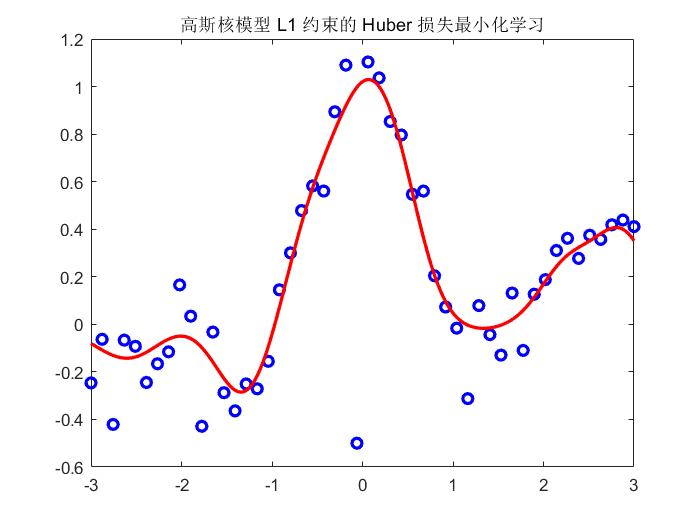

clear; clc;
rng('default');
n = 50;
N = 200;
x = linspace(-3, 3, n)';
X = linspace(-3, 3, N)';
% 生成带有噪声的训练数据
y = sin(pi*x) ./ (pi*x) + 0.1*x + 0.1*randn(n,1);
% 异常值
y(n/2) = -0.5;
hh = 2*0.3^2;
% 正则化参数
lam = 0.1;
% 阈值
e = 0.1;
% 初始值
t0 = randn(n, 1);
x2 = x.^2;
% 核函数
k = exp(-(repmat(x2, 1, n) + repmat(x2', n, 1) - 2*(x*x')) / hh);
for ite = 1 : 1000
    % 残差
    r = abs(k*t0 - y);
    % Huber损失最小化
    w = ones(n, 1);
    w(r > e) = e ./ r(r > e);  
    % L1 约束
    Z = k*(repmat(w, 1, n) .* k) + lam*pinv(diag(abs(t0))); 
    t = Z \ (k*(w.*y));   
    if norm(t - t0) < 1e-3
        break
    end
    t0 = t;
end
K = exp(-(repmat(X .^ 2, 1, n) + repmat(x2', N, 1) - 2*X*x') / hh);
F = K*t;
figure;
plot(x, y, 'ob', 'LineWidth', 2);
hold on;
plot(X, F, 'r', 'LineWidth', 2);
hold off
title('高斯核模型 L1 约束的 Huber 损失最小化学习');